Course: 22050 - Signals and linear systems in discrete time

Group: 01

Group members: Lubaba (sxxx), Nafissa (sxxx), Henning (sxxx), Amal (s224017)

# 1st draft: Project assignment - A basic DSP pipeline

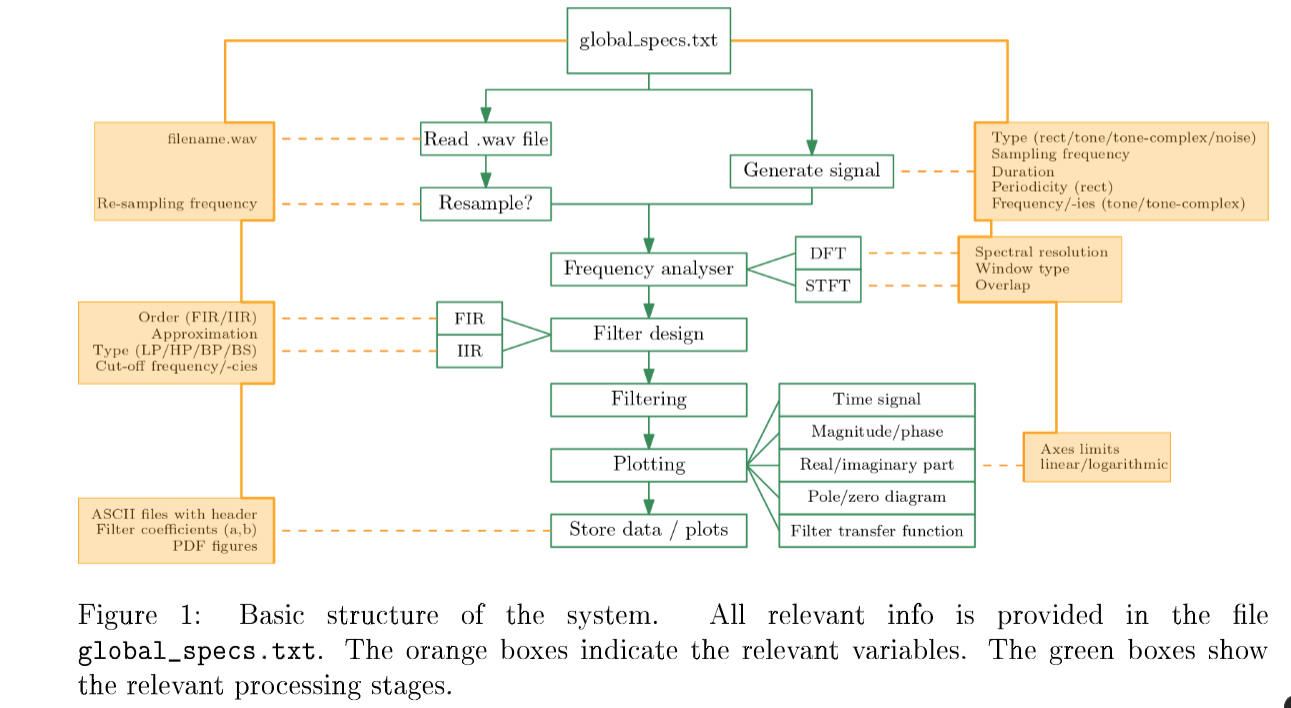

*Copied from assigntment document*

## 1 Introduction to main

This livescript runs the complete DSP processing pipeline as specified by `global_specs.txt`. 

All output plots (10x15 cm PDFs) is saved in `/figures`. Filter coefficients and processed signals can be found in the folder `/output`, where they have been saved.

## 2 Cleaning workspace and setting up paths

% Clean workspace
clc;
close all;
clear;

% Setup paths
addpath('functions');
addpath('sounds');
addpath('figures');
addpath('outputs');

## 3 Reading specification


specs = read_specs('global_specs.txt');

Not enough input arguments.

Error in read_specs (line 5)
outputArg2 = inputArg2;

## 4 Signal generation or preprocessing of signal

Resampling

if strcmpi(specs.X, 'wav')
    x = preprocess_signal(specs);
else
    x = generate_signal(specs); % We already have this on from assignment 2!
end



## 5 Filtering

This section involves filtering ...

### 5.1 Frequency response 

DFT/STFT?

### 5.2 Filter design

H = design_filter(specs);

### 5.3 Apply filter

y = apply_filter(x, H, specs);


## 6 Output

This section is about analyze output and plotting (maybe we should split into two functions or rename the function?) ...

### 6.1 Analyzing output

analyze_output(y, H, specs);


### 6.2 Plotting and saving

% Save as .mat file maybe?

Finally: print "successful" or something?

# Notes:

**Pitfalls we should be prepared for:**

- How should we handle a sampling rate that is too small? Should we throw error or just assert "sampling frequency too low -> aliasing will/may occur" in the function `read_specs`?  

- Normalising/clipping signals after processing before audio is saved

- Filter instability with IIR's(but we will have to wait until week 11 with this!)

- IIR filter delay, zero phase filtering

- Spectral leakage -> windowing